## Parareal Algorithm for a system of ODEs

Test the parareal algorithm on a system of (two) ODEs (Lotka Volterra two species)

clear all; close all; clc;

### Set parameters of the ODEs system

% params
T = 300;
y0 = [15, 15];
N_coarse = 150;
dT = T/N_coarse;
dt = 0.002;
N_fine = dT/dt

N_fine = 1000

### Solve the system of ODEs

% compute first the "reference" sol
tic
[t_ref, y_ref] = ode45(@(t, y) fun(t, y), [0, T], y0);
time_ref = toc;

% compute sequential sol (only coarse solver)
tic
steps = N_coarse * N_fine;
y_seq = sequential(T, y0, steps);
time_seq = toc;

% parareal
tic
[t_par, y_par] = parareal(T, y0, N_coarse, N_fine);

iteration 1/150
incr = NaN


iteration 2/150
incr = NaN


iteration 3/150
incr = NaN


iteration 4/150
incr = NaN
iteration 5/150
incr = NaN
iteration 6/150
incr = NaN
iteration 7/150
incr = NaN
iteration 8/150
incr = NaN
iteration 9/150
incr = NaN
iteration 10/150
incr = NaN
iteration 11/150
incr = NaN
iteration 12/150
incr = NaN
iteration 13/150
incr = NaN
iteration 14/150
incr = NaN
iteration 15/150
incr = NaN
iteration 16/150
incr = NaN
iteration 17/150
incr = NaN
iteration 18/150
incr = NaN
iteration 19/150
incr = NaN
iteration 20/150
incr = NaN
iteration 21/150
incr = NaN
iteration 22/150
incr = NaN
iteration 23/150
incr = NaN
iteration 24/150
incr = NaN
iteration 25/150
incr = NaN
iteration 26/150
incr = NaN
iteration 27/150
incr = NaN
iteration 28/150
incr = NaN
iteration 29/150
incr = NaN
iteration 30/150
incr = NaN
iteration 31/150
incr = NaN
iteration 32/150
incr = NaN
iteration 33/150
incr = NaN
iteration 34/150
incr = NaN
iteration 35/150
incr = NaN
iteration 36/150
incr = NaN
iteration 37/150
incr = NaN
iteration 38/150
incr = NaN
iteration 39/150
incr = Na

time_par = toc;

### Display results

err = norm(y_ref(end,:) - y_par(end,:));
disp(['error of parareal: ' num2str(err)])

error of parareal: 2.3279


err = norm(y_ref(end,:) - y_seq(end,:));
disp(['error of sequential: ' num2str(err)])

error of sequential: 1.6489


disp(' ')

disp(['time_ref: ' num2str(time_ref)])

time_ref: 0.10183


disp(['time_seq: ' num2str(time_seq)])

time_seq: 0.14178


disp(['time_par: ' num2str(time_par)])

time_par: 12.24


### Plots

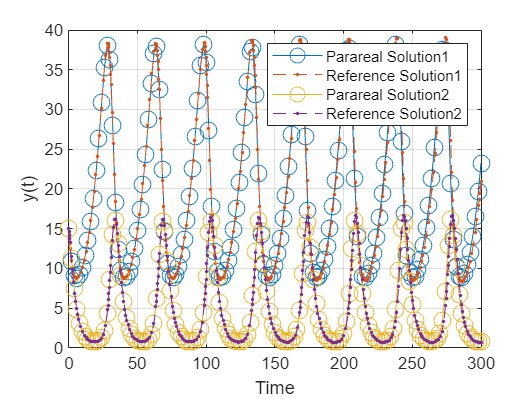

dim = length(y0);
for i=1:dim
    plot(t_par, y_par(:,i), 'o-', 'MarkerSize', 10, 'DisplayName', ['Parareal Solution', num2str(i)]);
    hold on;
    plot(t_ref, y_ref(:,i), '.--', 'DisplayName', ['Reference Solution', num2str(i)]);
end
hold off;
xlabel('Time');
ylabel('y(t)');
legend();
grid on;